clear all

% get group cell arrays made first in a  seperate loop

% at this point, vars 4 indivisual & group analysis have already been created

% have matlab ask me how many mice I wanna average over for the present group
clear nGroup
nGroup = input('how many sessions in this group?')

nGroup =      2



% put that number into a for loop, have me get the var mat files that many of times

clear nthVarsFilePaths
clear n
for n = 1:nGroup
    
    [f p] = uigetfile('*.mat',sprintf('session # %0.00f vars4IndAndGroupAnalyses',n));
    
    % make cell array w/ sessions for columns
    % & file names/paths for values down the rows
    
    nthVarsFilePaths{1,n} = f;
    nthVarsFilePaths{2,n} = p;
    
    % load the nth var mat file
    load(fullfile(p,f));
    
    % put each var (could be a struct, double, etc) into a column of a cell array: 
    % all group cell arays will be % 1 x # sessions
    groupStimDetails{1,n} = stimDetails;
    groupSubjData{1,n} = subjData; 
    groupSubjName{1,n} = subjName;
    groupDate{1,n} = date;
    groupTrialCond{1,n} = trialCond;
    groupNumPreStimFrames{1,n} = numPreStimFrames;
    groupNumPostStimFrames{1,n} = numPostStimFrames;
    groupIdxOnsetsMeetsCriteria{1,n} = idxOnsetsMeetsCriteria;
    groupPeakFrameIdx{1,n} = peakFrameIdx;
    groupStimOnsetFrame{1,n} = stimOnsetFrame;
    groupBaselineIdx{1,n} = baselineIdx;
    groupMeanActImFrames{1,n} = meanActImFrames;
    groupRoundXpts{1,n} = RoundXpts;
    groupRoundYpts{1,n} = RoundYpts;
    groupPTSdfof{1,n} = PTSdfof;
    groupMeanSpeedAllTrials{1,n} = meanSpeedAllTrials;
    groupIdxRunTrials{1,n} = idxRunTrials;
    groupIdxStatTrials{1,n} = idxStatTrials;
    
end % now I have the group analysis vars for each session


% Ah fuck this is the problem... I *do* need to make a new matrix for 
% run vs stat, b/c my group matrix is a crf...
% and I can't make a group matrix that has all trials, b/c there's a 
% diff number of trials per session...
% and I don' think I can index directly into structures, I have to
% 'extract them and make the matrix on the fly...
% and then I can plot in the 2nd code cell...

% LOG RUN vs STAT CRF but also plot INDIVIDUAL SESS TRACES

% EXTRACT VARS & MAKE GROUP MATRIX (duration x crf values x points x session
% RUN vs STAT

% LOG

% for STAT

clear allSessAllPtsAllDurCRFminusMeanBase % clearing final group matrix just in case not running script from top (clear all)
clear n 
for n = 1:nGroup % for each session/mouse
            
    % EXTRACT VARS from GROUP CELL ARRAYS
    nthStimDetailsStruct = groupStimDetails{n};
    nthTrialCond = groupTrialCond{1,n};
    nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
   
    % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
    
    % CONTRAST calc's
    clear con
    clear conOrderedByTrial  
    clear conOrderedByTrialMeetCriteria 
    clear uniqueContrasts
    clear c % % still in session loop, for each stim condition, get contrast value, store all in vector
    for c = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
        con(c) = nthStimDetailsStruct(c).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
    end
    conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
    conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    uniqueContrasts = unique(con); % for looping over contrast values later
    
    %%  DURATION Calc's
    clear dur
    clear durOrderedByTrial  
    clear durOrderedByTrialMeetCriteria 
    clear uniqueDurations
    % extract duration field from stimDetails
    clear d
    for d = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
        dur(d) = nthStimDetailsStruct(d).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
    end
    durOrderedByTrial = dur(nthTrialCond); 
    durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    uniqueDurations = unique(dur);
    
    %% CON & DUR TOGETHER
    clear conAndDur 
    clear conAndDurOrderedByTrial 
    clear conAndDurOrderedByTrialMeetCriteria
    conAndDur = [con; dur];
    conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
    conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthPTSdfof = groupPTSdfof{1,n};
    nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
    nthBaselineIdx = groupBaselineIdx{1,n};
    
    % EXTRACT RUN vs STAT TRIAL INDICIES
    nthIdxRunTrials = groupIdxRunTrials{1,n};
    nthIdxStatTrials = groupIdxStatTrials{1,n}; 

    % make a group matrix w/CRF for each session, dur, point 
    % one for RUN & one for STAT
    
    % MATRIX FOR ALL TRIALS EAch SESSION
    
    % for each POINT
    clear i 
    for i = 1:length(RoundXpts) 
        
        % for each point, make/append a new all durations CRF matrix:
        clear allDurCRFminusMeanBase
        
        % calulate crf for each DURATION
        clear d 
        for d = 1:length(uniqueDurations)
            
            % CALCULATE CRF per DUR
            clear meanBaselineFramesIthPtDthCthTrials
            clear dthCRF
            clear dthCRFminusBaseline
            clear durConStdErr
                           
            clear c
            for c = 1:length(uniqueContrasts) 
                                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,nthIdxStatTrials);
             
                % this is the same as the CRF process from earlier code
                % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(nthPTSdfof(i,nthPeakFrameIdx,idxCthDthSTATtrials));
                % take the mean over frames
                % returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now take the mean over trials
                clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
                % now I want to collect each CRF vector for the ith point (not saving dur value info here yet)
                % creates 1 x # contrasts for the d-th duration
                dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for
                % the ith point and cth contrast
                % get all frames & cth trials
                clear baselineFramesIthPtDthCthTrials
                baselineFramesIthPtsDthCthTrials = squeeze((nthPTSdfof(i,nthBaselineIdx,idxCthDthSTATtrials)));
                % now have baseline frames x trials
                % take mean across trials 
                clear meanBaselineFrameIthPtDthCthTrials
                meanBaselineFramesIthPtsDthCthTrials = mean(baselineFramesIthPtsDthCthTrials,2);
                % take mean across frames
                meanBaselineFramesIthPtsDthCthTrials = mean(meanBaselineFramesIthPtsDthCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                dthCRFminusBaseline(c) = dthCRF(c)-meanBaselineFramesIthPtsDthCthTrials; % clear this var in between durations
                % allSessAllPtsDthCRFminusMeanBase(i,:,n) = dthCRFminusBaseline;
                 
                % indivdual STDERR
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(idxCthDthSTATtrials)); % sum trials, not length
                durConStdErr(1,c) = stdErr; 
                % saving just in case:
                % PTS x STDERR x SESSION matrix
                % allSessAllPtsDurStdErr(i,:,n) = durStdErr;
                 
            end % end c loop - still inside d loop, i loop, and n loop 
                
            % put DTH CRF into a MATRIX with CRF for each DUR (rows = dur, columns = CRF values)
            allDurCRFminusMeanBase(d,:) = dthCRFminusBaseline;
                
        end % end d loop- % once I've gone thru the d loop completely the first time, 
        % now I've got a matrix for the dth crfs at one point and one session - save for that point before onto the next point
        allPtsAllDurCRFminusMeanBase(:,:,i) = allDurCRFminusMeanBase;
            
    end % end i loop - 
    
    % SAVE EACH SESSION IN MATRIX
    % now you have all dthCRF's for all points for one session - 
    % save matrix with session to before go onto next session
    allSessAllPtsAllDurCRFminusMeanBase(:,:,:,n) = allPtsAllDurCRFminusMeanBase;
      
end % end n loop - group STAT matrix is complete

size(allSessAllPtsAllDurCRFminusMeanBase)


ans =      1     7     5     2


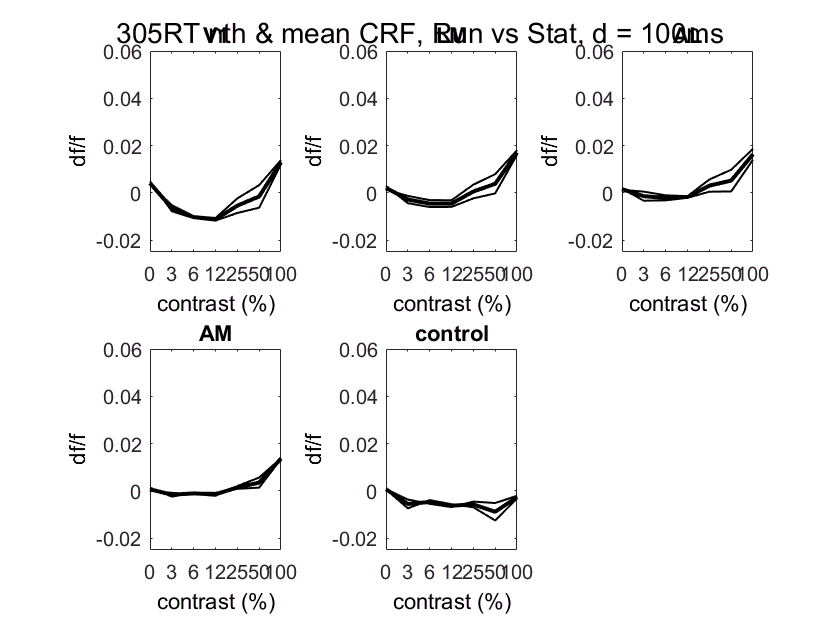

% PLOT EACH STAT SESSION - need to do this outside the matrix loop cuz you will take mean over all sessions

figure % one fig, subplot for each point, mean CRF for each dur plotted for each point
% (crf was calulated per duration vale, point, and session eariler
% in 'allSessAllPtsAllDurCRFminusMeanBase')
suptitle('305RT nth & mean CRF, Run vs Stat, d = 100ms')
clear i
for i = 1:length(RoundXpts) % for each point
    
    % (this code is for plotting individual lines as well as mean
    
    clear n
    for n = 1:nGroup % for each session
        
        % legned info, per group
        
        reigons = {'V1','LM','AL','AM','control'};

        cons4Legend = arrayfun(@num2str, uniqueContrasts, 'UniformOutput', 0); % max contrast is '1'
        cons4Axes = arrayfun(@num2str, uniqueContrasts*100, 'UniformOutput', 0); % max contrast is 100% 

        durs4Legend = arrayfun(@num2str, uniqueDurations, 'UniformOutput', 0);
        durs4Axes = durs4Legend;
        
        clear d
        for d = 1:length(uniqueDurations) % for each duration
            
            % plot CRF for each duration using GROUP MATRIX
            % extract ith point nth sess all dth crfs (duration x crf values x point x session)
            nthSessIthPtAllDthCRFminusBase = allSessAllPtsAllDurCRFminusMeanBase(:,:,i,n);
            % should be duration x contrast
            nthSessIthPtAllDthCRFminusBase = squeeze(nthSessIthPtAllDthCRFminusBase); % squeeze
            % extract DTH CRF for NTH session
            nthSessDthCRFithPt = nthSessIthPtAllDthCRFminusBase(d,:);

            subplot(2,3,i) 
            x_axis = [1:length(nthSessDthCRFithPt)]; % for the length of the dth crf
            plot(x_axis,nthSessDthCRFithPt,'-k','linewidth',1);
            title(reigons{i})
            
            ylim([-0.025 0.06]) 
            xlim([min(x_axis), max(x_axis)])
            ylabel('df/f')
            xlabel('contrast (%)')
            
            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            set(gca,'xtick',1:7); 
            set(gca,'xticklabel',xt);
            
            hold on % stay in d loop, plot all dth CRFs for this n & i 
            
        end % end d loop and do the same thing 
        % (plot all nth session's dth crfs) for the next session at this point
        
        hold on % use same subplot for next session
        
    end % end n loop, still in i loop 
    
    % I have all dCRFs for all sessions plotted at this point, now
    % plot all mean (across sessions) dthCRF traces for ith point, 
    % before move onto next point/subplot
    
    % PLOT MEAN STAT TRACE 
    
    hold on % same subplot for mean trace
    
    % we are still at the ith point/subplot
    clear d
    for d = 1:length(uniqueDurations) % for each duration
    
        % using group matrix, calulate mean dth CRF
        % dur x crf value x point x session
        clear dthCRF
        dthCRF = allSessAllPtsAllDurCRFminusMeanBase(d,:,i,:); % take for all sessions
        dthCRF = squeeze(dthCRF)'; % squeeze & transpose
        clear meanAcrossSessDthCRF
        meanAcrossSessDthCRF = mean(dthCRF,1);
        
        % I think this is how to calulate group STDERR?:
        clear groupStdErr
        groupStdErr = std(dthCRF,1)/(sqrt(nGroup));
              
        % plot dth CRF on ith subplot:
        subplot(2,3,i) 
        x_axis = [1:length(uniqueContrasts)];
        plot(x_axis,meanAcrossSessDthCRF,'-k','linewidth',2)
        title(reigons{i})
        
        ylim([-0.025 0.06]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')
        
        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on % hold on to plot next mean dth CRF on the ith subplot
        
    end % end duration loop, move to next point, repeat whole process
    
    % no n loop cuz plotting mean *over* traces
    
    %legend(durs4Legend)
    
end % end i loop

hold on

% for RUN

clear allSessAllPtsAllDurCRFminusMeanBase % clearing final group matrix just in case not running script from top (clear all)
clear n 
for n = 1:nGroup % for each session/mouse
            
    % EXTRACT VARS from GROUP CELL ARRAYS
    nthStimDetailsStruct = groupStimDetails{n};
    nthTrialCond = groupTrialCond{1,n};
    nthIdxOnsetsMeetsCriteria = groupIdxOnsetsMeetsCriteria{1,n}; 
   
    % CON & DUR VALUES AT EACH TRIAL - these values get calculated anew for each session 
    
    % CONTRAST calc's
    clear con
    clear conOrderedByTrial  
    clear conOrderedByTrialMeetCriteria 
    clear uniqueContrasts
    clear c % % still in session loop, for each stim condition, get contrast value, store all in vector
    for c = 1:length(nthStimDetailsStruct); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
        con(c) = nthStimDetailsStruct(c).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
    end
    conOrderedByTrial = con(nthTrialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
    conOrderedByTrialMeetCriteria = conOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    uniqueContrasts = unique(con); % for looping over contrast values later
    
    %%  DURATION Calc's
    clear dur
    clear durOrderedByTrial  
    clear durOrderedByTrialMeetCriteria 
    clear uniqueDurations
    % extract duration field from stimDetails
    clear d
    for d = 1:length(nthStimDetailsStruct); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
        dur(d) = nthStimDetailsStruct(d).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
    end
    durOrderedByTrial = dur(nthTrialCond); 
    durOrderedByTrialMeetCriteria = durOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    uniqueDurations = unique(dur);
    
    %% CON & DUR TOGETHER
    clear conAndDur 
    clear conAndDurOrderedByTrial 
    clear conAndDurOrderedByTrialMeetCriteria
    conAndDur = [con; dur];
    conAndDurOrderedByTrial = conAndDur(:,nthTrialCond); % gives 2 x #trials
    conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,nthIdxOnsetsMeetsCriteria);
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthPTSdfof = groupPTSdfof{1,n};
    nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
    nthBaselineIdx = groupBaselineIdx{1,n};
    
    % EXTRACT RUN vs STAT TRIAL INDICIES
    nthIdxRunTrials = groupIdxRunTrials{1,n};
    nthIdxStatTrials = groupIdxStatTrials{1,n}; 

    % make a group matrix w/CRF for each session, dur, point 
    % one for RUN & one for STAT
    
    % MATRIX FOR ALL TRIALS EAch SESSION
    
    % for each POINT
    clear i 
    for i = 1:length(RoundXpts) 
        
        % for each point, make/append a new all durations CRF matrix:
        clear allDurCRFminusMeanBase
        
        % calulate crf for each DURATION
        clear d 
        for d = 1:length(uniqueDurations)
            
            % CALCULATE CRF per DUR
            clear meanBaselineFramesIthPtDthCthTrials
            clear dthCRF
            clear dthCRFminusBaseline
            clear durConStdErr
                           
            clear c
            for c = 1:length(uniqueContrasts) 
                                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,nthIdxRunTrials);
             
                % this is the same as the CRF process from earlier code
                % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
                % returns 3 (frames) by # trials
                clear sq5FramesOverTrialsPTSdfof
                sq5FramesOverTrialsPTSdfof = squeeze(nthPTSdfof(i,nthPeakFrameIdx,idxCthDthRUNtrials));
                % take the mean over frames
                % returns 1 x # trials
                clear meanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
                % now take the mean over trials
                clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
                meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
                % now I want to collect each CRF vector for the ith point (not saving dur value info here yet)
                % creates 1 x # contrasts for the d-th duration
                dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
                % GET mean BASEline
                % the baseline for each CRF value is the mean of the baseline frames for
                % the ith point and cth contrast
                % get all frames & cth trials
                clear baselineFramesIthPtDthCthTrials
                baselineFramesIthPtsDthCthTrials = squeeze((nthPTSdfof(i,nthBaselineIdx,idxCthDthRUNtrials)));
                % now have baseline frames x trials
                % take mean across trials 
                clear meanBaselineFrameIthPtDthCthTrials
                meanBaselineFramesIthPtsDthCthTrials = mean(baselineFramesIthPtsDthCthTrials,2);
                % take mean across frames
                meanBaselineFramesIthPtsDthCthTrials = mean(meanBaselineFramesIthPtsDthCthTrials,1);
            
                % do BASEline CORRECTION
                % subtract the cth baseline from the flourescence at each c
                dthCRFminusBaseline(c) = dthCRF(c)-meanBaselineFramesIthPtsDthCthTrials; % clear this var in between durations
                % allSessAllPtsDthCRFminusMeanBase(i,:,n) = dthCRFminusBaseline;
                 
                % indivdual STDERR
                clear stdErr
                stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(idxCthDthRUNtrials)); % sum trials, not length
                contStdErr(1,c) = stdErr; 
                % saving just in case:
                % PTS x STDERR x SESSION matrix
                % allSessAllPtsDurStdErr(i,:,n) = durStdErr;
                 
            end % end c loop - still inside d loop, i loop, and n loop 
                
            % put DTH CRF into a MATRIX with CRF for each DUR (rows = dur, columns = CRF values)
            allDurCRFminusMeanBase(d,:) = dthCRFminusBaseline;
                
        end % end d loop- % once I've gone thru the d loop completely the first time, 
        % now I've got a matrix for the dth crfs at one point and one session - save for that point before onto the next point
        allPtsAllDurCRFminusMeanBase(:,:,i) = allDurCRFminusMeanBase;
            
    end % end i loop - 
    
    % SAVE EACH SESSION IN MATRIX
    % now you have all dthCRF's for all points for one session - 
    % save matrix with session to before go onto next session
    allSessAllPtsAllDurCRFminusMeanBase(:,:,:,n) = allPtsAllDurCRFminusMeanBase;
      
end % end n loop - group STAT matrix is complete

size(allSessAllPtsAllDurCRFminusMeanBase)


ans =      1     7     5     2


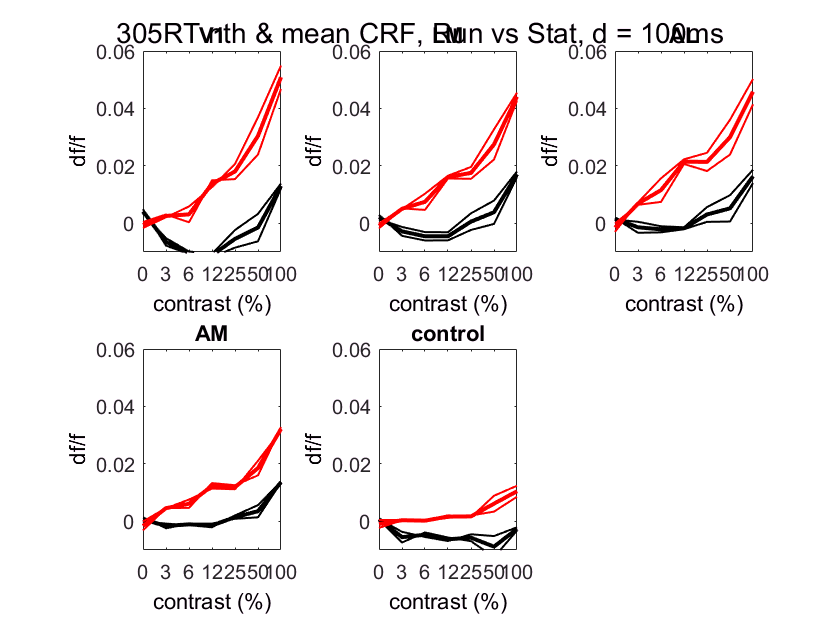

clear i
for i = 1:length(RoundXpts) % for each point
    
    % (this code is for plotting individual lines as well as mean
    
    clear n
    for n = 1:nGroup % for each session
        
        % legned info, per group
        
        reigons = {'V1','LM','AL','AM','control'};

        cons4Legend = arrayfun(@num2str, uniqueContrasts, 'UniformOutput', 0); % max contrast is '1'
        cons4Axes = arrayfun(@num2str, uniqueContrasts*100, 'UniformOutput', 0); % max contrast is 100% 

        durs4Legend = arrayfun(@num2str, uniqueDurations, 'UniformOutput', 0);
        durs4Axes = durs4Legend;
        
        clear d
        for d = 1:length(uniqueDurations) % for each duration
            
            % plot CRF for each duration using GROUP MATRIX
            % extract ith point nth sess all dth crfs (duration x crf values x point x session)
            nthSessIthPtAllDthCRFminusBase = allSessAllPtsAllDurCRFminusMeanBase(:,:,i,n);
            % should be duration x contrast
            nthSessIthPtAllDthCRFminusBase = squeeze(nthSessIthPtAllDthCRFminusBase); % squeeze
            % extract DTH CRF for NTH session
            nthSessDthCRFithPt = nthSessIthPtAllDthCRFminusBase(d,:);
            
            hold on
            
            subplot(2,3,i) 
            x_axis = [1:length(nthSessDthCRFithPt)]; % for the length of the dth crf
            plot(x_axis,nthSessDthCRFithPt,'-r','linewidth',1);
            title(reigons{i})
            
            ylim([-0.025 0.06]) 
            xlim([min(x_axis), max(x_axis)])
            ylabel('df/f')
            xlabel('contrast (%)')
            
            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            set(gca,'xtick',1:7); 
            set(gca,'xticklabel',xt);
            
            hold on % stay in d loop, plot all dth CRFs for this n & i 
            
        end % end d loop and do the same thing 
        % (plot all nth session's dth crfs) for the next session at this point
        
        hold on % use same subplot for next session
        
    end % end n loop, still in i loop 
    
    % I have all dCRFs for all sessions plotted at this point, now
    % plot all mean (across sessions) dthCRF traces for ith point, 
    % before move onto next point/subplot
    
    % PLOT MEAN RUN TRACE 
    
    hold on % same subplot for mean trace
    
    % we are still at the ith point/subplot
    clear d
    for d = 1:length(uniqueDurations) % for each duration
    
        % using group matrix, calulate mean dth CRF
        % dur x crf value x point x session
        clear dthCRF
        dthCRF = allSessAllPtsAllDurCRFminusMeanBase(d,:,i,:); % take for all sessions
        dthCRF = squeeze(dthCRF)'; % squeeze & transpose
        clear meanAcrossSessDthCRF
        meanAcrossSessDthCRF = mean(dthCRF,1);
        
        % I think this is how to calulate group STDERR?:
        clear groupStdErr
        groupStdErr = std(dthCRF,1)/(sqrt(nGroup));
              
        % plot dth CRF on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        %x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        plot(x_axis,meanAcrossSessDthCRF,'-r','linewidth',2) % -s seemed to get diff color for each dur?
        title(reigons{i})
        
        ylim([-0.01 0.06]) 
        xlim([min(x_axis), max(x_axis)])
        %ylim([-0.025 0.1]) 
        %xlim([0, 8])
        ylabel('df/f')
        xlabel('contrast (%)')
        
        hold on % hold on to plot next mean dth CRF on the ith subplot
        
    end % end duration loop, move to next point, repeat whole process
    
    % no n loop cuz plotting mean *over* traces
    
    %legend(durs4Legend)
    
end % end i loop